# Modsim Project 2

*Authors:* Rowan Jansens, Olivia Chang 

## Question

In the winter, people are often told to turn the heat down/off when they leave the house to save energy. However, there is also an argument that leaving the heat on when you leave is more efficient.  This model will seek to explain if there are any scenarios were leaving the heat on could be more energy efficient than turning it off when leaving the house for some amount of time.  Answering this question is important because it could resolve a potential spread of misinformation. In addition, it might help homeowners make more energy conscious decisions about their heating which would benefit their wallets and the environment.

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Learn how to create a good modeling question

- Understand best practices in structuring a thermodynamic model

- Write my own ODE’s / understand how to generate an equation for a modeling question

## Methodology

### Stock and Flow

To compare the efficiency of turning the heater off vs. leaving it on, a stock and flow model of a house was created.  In this simplified model, the stock is the internal energy of the house. A heater adds energy to the stock while the house loses energy though conduction. When the heater is on, it adds energy at a constant rate (\frac{dU}{dt} = W_{heater}) and when it is off, no heat is added. 

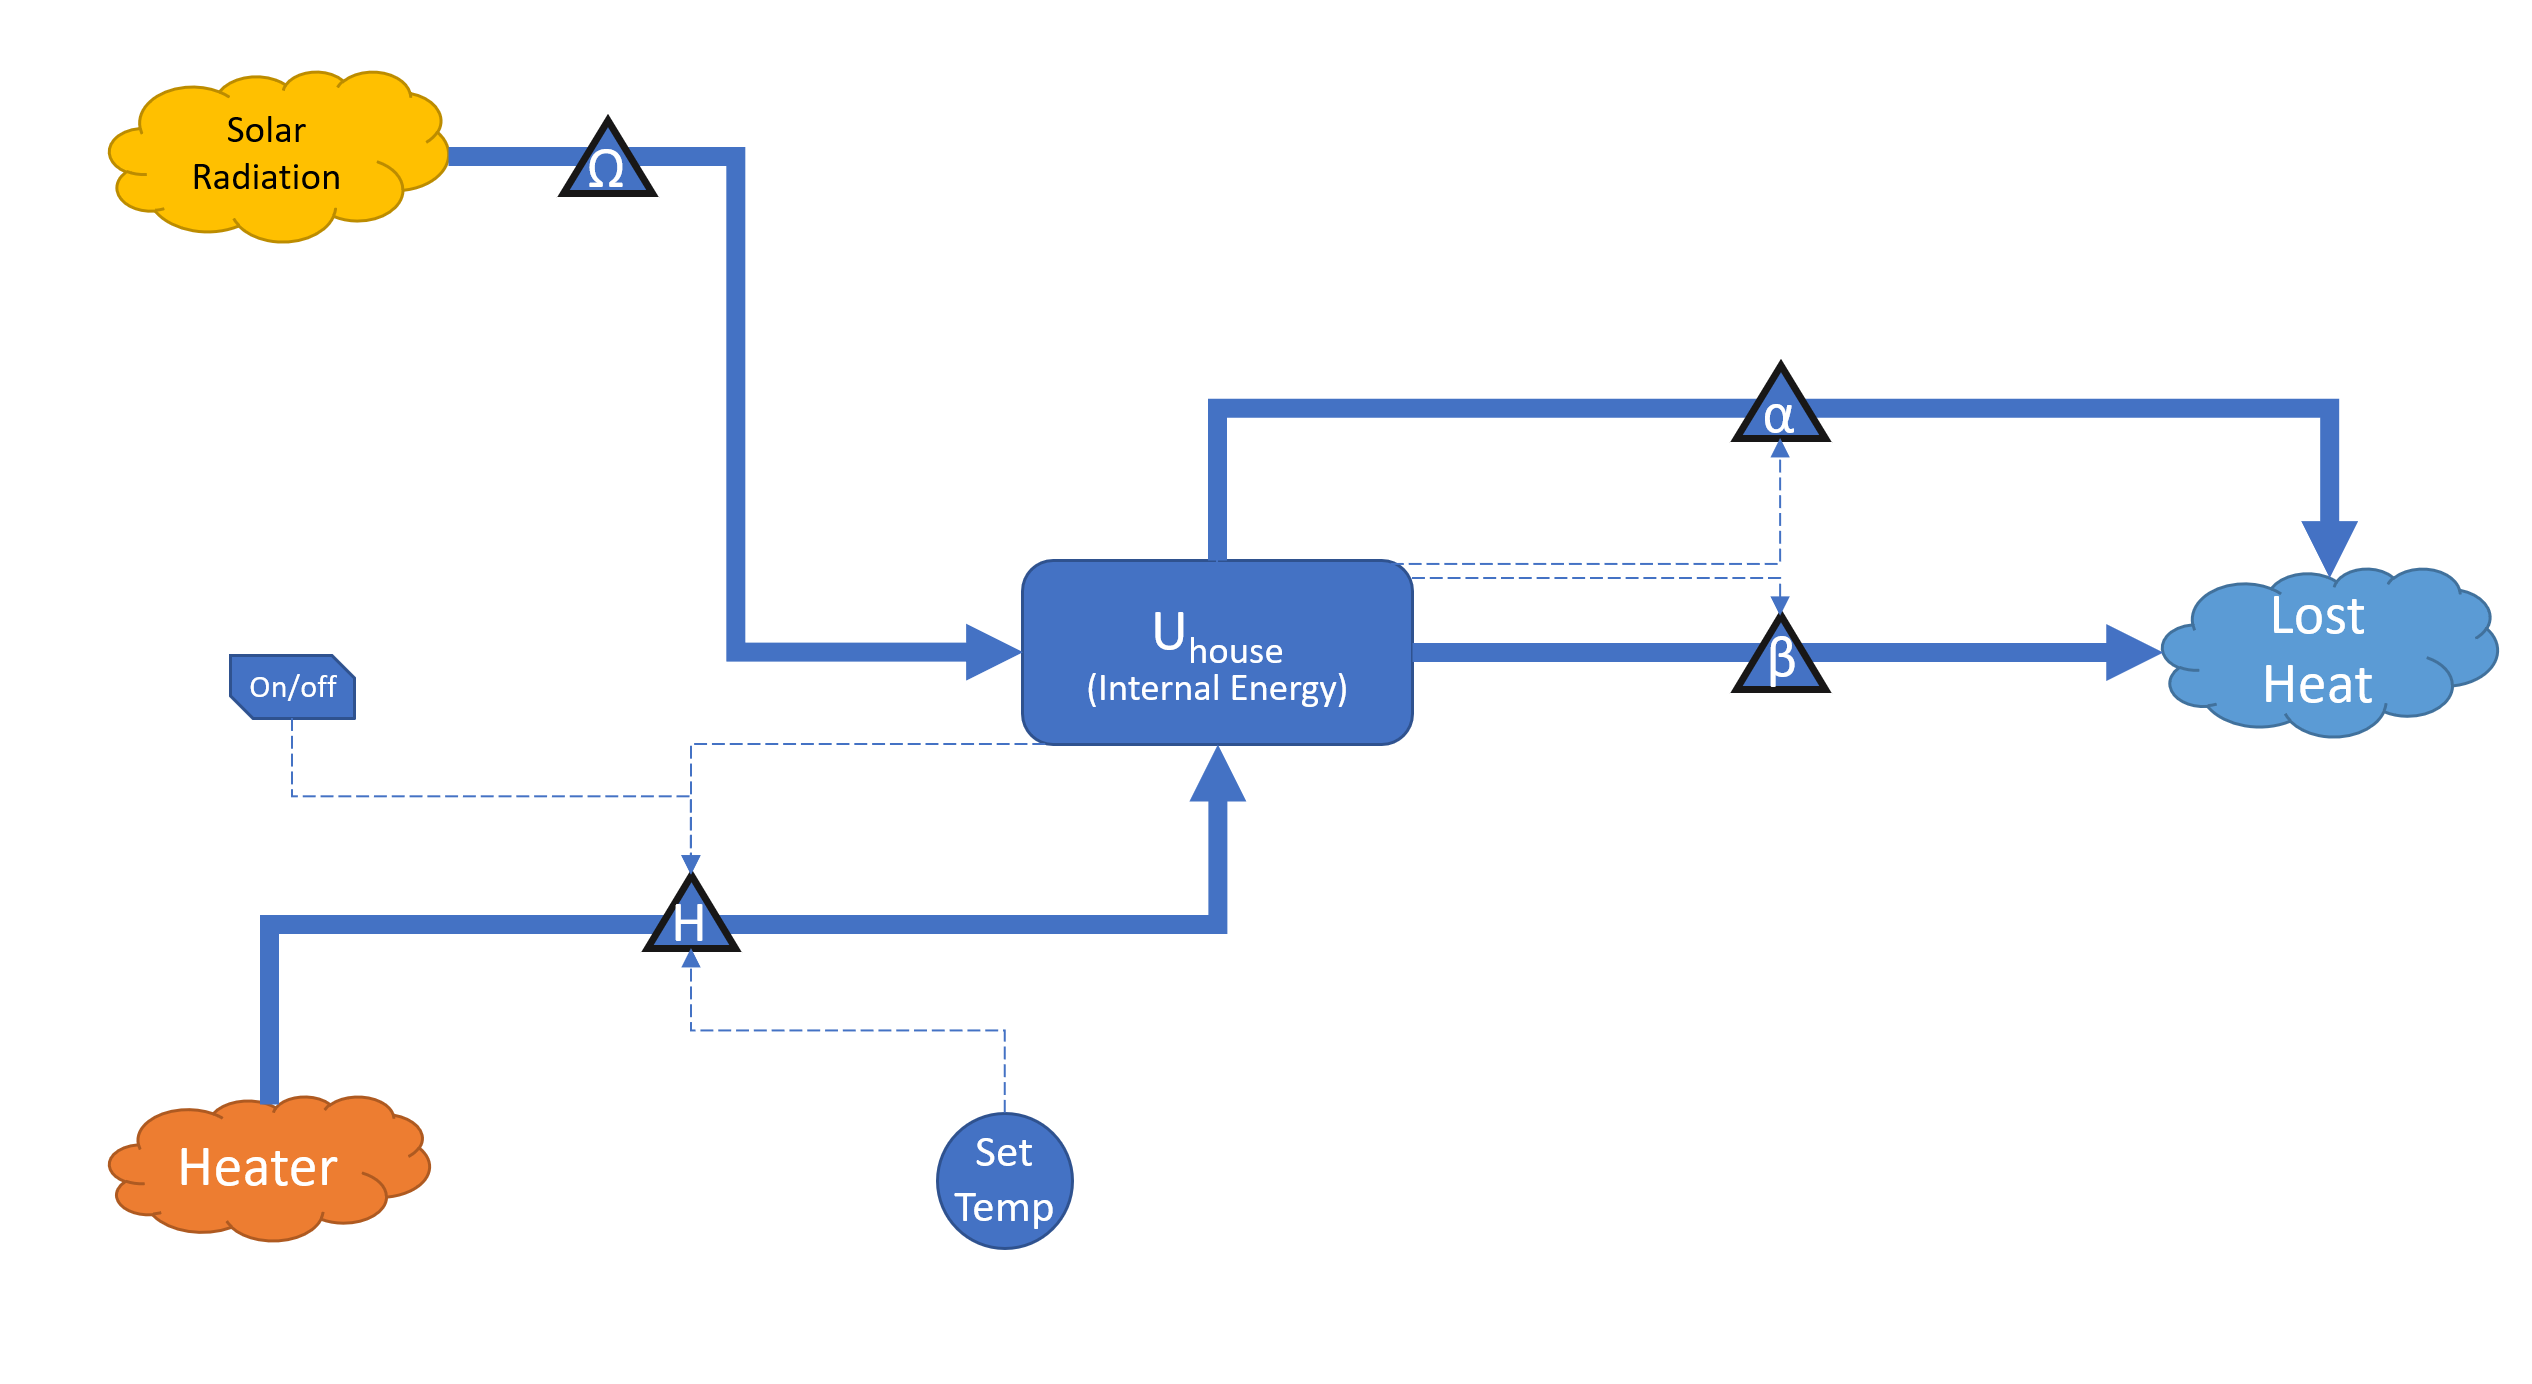

Flows in

- Gas Furnace Heating System: this is a forced input which depends on whether the house's current temperature is below the ideal temperature.

Flows out

- Conduction through walls

- Conduction through roof

### Parameters

#### Defining The House

The house was modeled after an "average" house in Massachusetts. The house used in this model is a house of width 10 meters, length 15 meters, and hieght 3 meters, giving the house a square meters value slightly lower than the average house in MA (162 m^2).

The house walls were modeled after the standard office building as according to the Department of Energy (citation), and were composed of gipsum, fiber batt, concrete, and stucco. We treated the only important insulating material in the roof (attic) as fiber batt; thus the roof is effectively made of only fiber batt. The floor is made out of concrete and has a thickness that is standard for residential construction.

In the model, we treated the thermal mass of the house as being composed of the floor and the air inside the house.

House Parameters

- **House Size: **as previously stated, the house is a 10x15x3 meter rectangular prism.

- **Wall Composition: **from the inside to outside, the walls are composed of 0.5 in gipsum, 2 in fiber batt, 8 in concrete, and 1 in stucco.

- **Roof Composition: **the roof is composed of 16 in fiber batt.

- **Floor Composition: **the floor is composd of 4 in concrete.

General Parameters

- **Ideal House Temperature: **the ideal temperature at which the house's residents in our scenario would like to keep the temperature. Set at 22 degrees C, which is a generally universal comfortable temperature.

- **Lowered House Temperature: **the temperature at which the house's residents would lower the temperature while gone. Set at 19 degrees C.

- **Ambient Temperature Minimum: **the minimum ambient (outside) temperature. As we are modeling the house in a Boston winter, a reasonable minimum value of 20 degrees F, or approximately - 7degrees C, is reasonable and matches historical averages for winter.

- **Ambient Temperature Range: **the amount that the ambient temperature increases throughout the day, as it gets warmer. 15 degrees F, or approximately 9 degrees C, is a reasonable range.

- **Heater Power: **most homes in America use a gas powered furnace for heat. These appliances generally range in power from 15,000 to 35,000 kWh. We chose 25,000 kWh as the heater used in the house.

Scenario Parameters

- **Time Of Day That Resident Leaves House: **assumed in all scenarios to be 9 am, which is a normal time to leave for work.

- **Length Time Resident Is Gone From House: **the parameter that we're varying

- **Simulation Length: **24 hours. Each simulation is kept at the same length to ensure that the 

### Mathematical Model

From the stock and flow diagram, the following differential equation is generated.


$$\frac{dU}{dt} = H\Phi  + \Omega  - \frac{\Delta T}{R_{tot}}$$


 Where:

- $U$ is the internal energy of the house

- $H$ is the wattage of the heater

- $\Phi$ is a logical value indicating if the heater is on or off

- $\Omega$ is the energy of the sun in Watts

- $\Delta T$ is the temperature difference between the house and the environment

- $R_{tot}$ is the total conductive resistivity of the house

To calculate if the heater is on or off ($\Phi$), the model uses a discrete “overshoot and undershoot control band” which is commonly found in household thermostats. This causes the temperature of the house to oscillate around the set temperature and allows the heater to turn on less frequently.

This control system will be maintained in both scenarios while the set temperature will be varied to reflect keeping the heater on vs. turning it off. A parameter sweep can then be carried out to probe the effects of the different parameters in the model and compare the efficiencies of the two scenarios.

To calculate the total energy ($E$) used by the heater in order to assess each scenario, the model also tracks $\frac{dE}{dt} = H\Phi$

### Assumptions

[heat is only being lost through the roof and the walls. not the floor]

[lack of solar radiation]

[winter]

The house being modeled is very simple: the walls have no windows or doors, and it does not contain any internal walls, furniture, appliance, etc. Therefore, the thermal mass of the house can only be a crude estimate.  However, because this generalization will affect both scenarios (heater on vs. heater off), the relative comparisons will be informative for our question.

In addition, all the house’s internal energy is modeled by a single stock. In other words, we are assuming that the system is quasi static. This is reasonable because the rate at which the heater heats the air likely slower than the rate the air heats the solid material in the house. 

### Global Variables/Conversions

Note: for every function that needs these variables, the first line of code must be added in the top.

global k_to_c hours_to_seconds effective_off_temp ideal_temp freezing_temp heater_power;
k_to_c = 273;
hours_to_seconds = 60*60;
effective_off_temp = -10 + k_to_c;
ideal_temp = 22 + k_to_c; % 22
freezing_temp = 0 + k_to_c;
down_temp = 19 + k_to_c; % 13
heater_power = 25000; % watts, Heater power

### **Verification and Validation**

#### **Verifying thermostat logic**

To verify the implementation of the model, a test scenario was generated. The house is initially at 15 C while the set temperature is set to 22 C for 6 hours, then the set temperature is turned down to 0 C for 6 hours, then the set temp is restored to 22 C for yet another 6 hours. 0 C is far below the house temperature, so we can confidently assume that the house will never reach this temperature, meaning that the thermostat is effectively off.

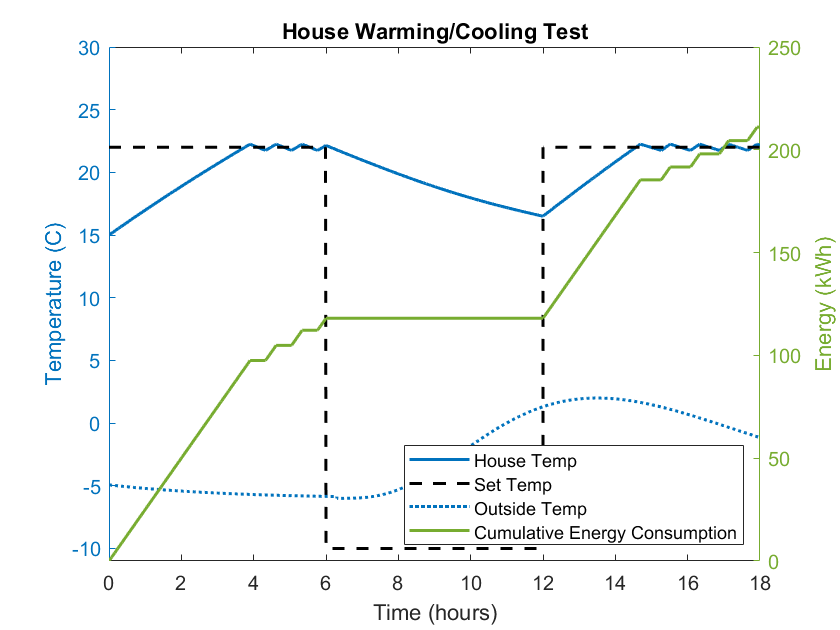

graph_title = "House Warming/Cooling Test";
% Set temp is a row matrix with the value of the desired temperature at a
% given second. Allows us to simulate the user turning down the heat and
% turning it up.

%define row matrix with set temperatures over time
set_temp_range = [ideal_temp*ones(1,6*hours_to_seconds), effective_off_temp*ones(1,6*hours_to_seconds), ideal_temp*ones(1,6*hours_to_seconds)];

%call ODE solver
[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, 288);

%plot results
plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-11 30])

dispOnTime(on_time)

Total on time: 8.4403hours


## Results

#### Heater on for 12 hours at set temp 20 C

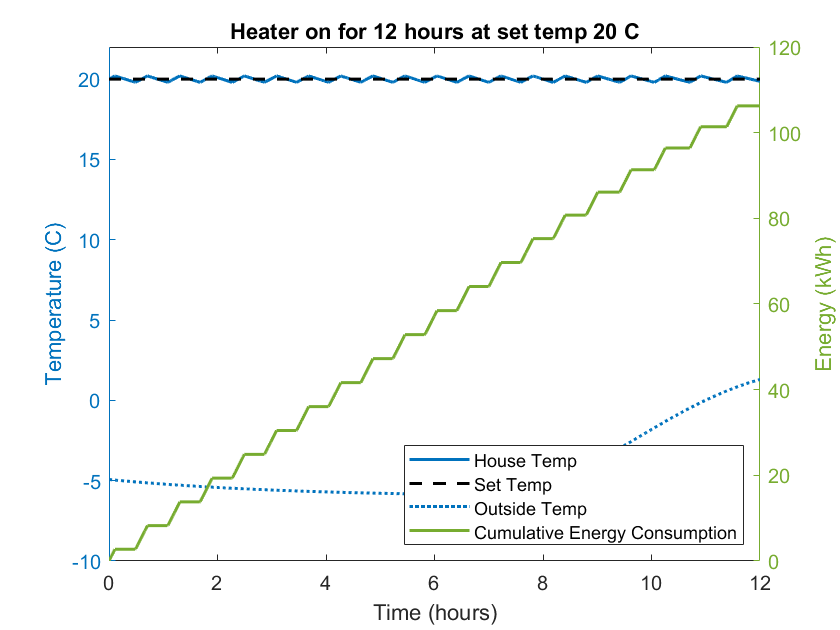

graph_title = 'Heater on for 12 hours at set temp 20 C';
set_temp = (20 + k_to_c);
set_temp_range = [set_temp*ones(1,12*hours_to_seconds)];
initial_house_temp = set_temp;

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-10 22])

dispOnTime(on_time)

Total on time: 4.2497hours


#### Heater off for 12 hours, then turn on at set temp 20 C

Initial house temperature is set temp.

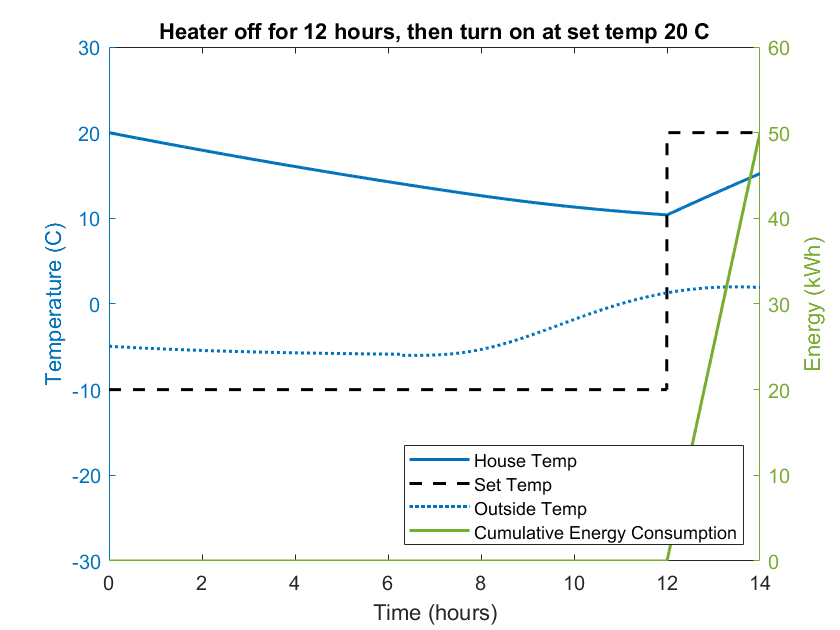

graph_title = 'Heater off for 12 hours, then turn on at set temp 20 C';
set_temp = (20 + k_to_c);
set_temp_range = [effective_off_temp*ones(1,12*hours_to_seconds), set_temp*ones(1,2*hours_to_seconds)];
initial_house_temp = set_temp;

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-30 30])

dispOnTime(on_time)

Total on time: 2.0003hours


#### Heater at 12 degrees C for 12 hours, then up to 20 C

Initial house temperature is set temp.

Note: this is exactly the same as the previous one because we haven't taken weather changes into account (i'm assuming)

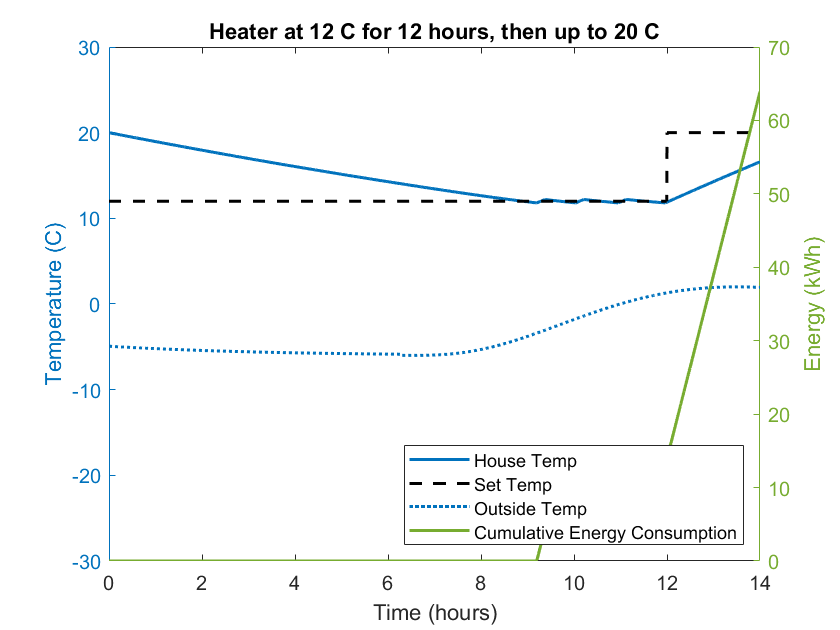

graph_title = 'Heater at 12 C for 12 hours, then up to 20 C';
set_temp_range = [(12 + k_to_c)*ones(1,12*hours_to_seconds), (20 + k_to_c)*ones(1,2*hours_to_seconds)];
initial_house_temp = (20 + k_to_c);

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-30 30])

dispOnTime(on_time)

Total on time: 2.5575hours


hour_leave_house = 9; % time you leave the house in hours (military) 
simulation_length = 24; % run simulation for 24 hours each time 

% sweep time_gone from 0 hr to 8 hours
sweep_range = [0.5:0.5:8];

sweep_results = zeros(size(sweep_range, 2), 3);

for i = 1:size(sweep_range, 2)
     time_gone = sweep_range(i);
     time_until_end_of_simulation = simulation_length - time_gone - hour_leave_house;
     
     turn_off_range = [(ideal_temp)*ones(1,hour_leave_house*hours_to_seconds), (effective_off_temp)*ones(1,time_gone*hours_to_seconds), (ideal_temp)*ones(1,time_until_end_of_simulation*hours_to_seconds)];
     turn_down_range = [(ideal_temp)*ones(1,hour_leave_house*hours_to_seconds), (down_temp)*ones(1,time_gone*hours_to_seconds), (ideal_temp)*ones(1,time_until_end_of_simulation*hours_to_seconds)];     
     
     [time_range, temperature, energy_consumption, turn_off_on_time, outside_temp] = house_cooling(turn_off_range, ideal_temp);
     [time_range, temperature, energy_consumption, turn_down_on_time, outside_temp] = house_cooling(turn_down_range, ideal_temp);
     
     sweep_results(i, 1) = time_gone;
     sweep_results(i, 2) = turn_off_on_time;
     sweep_results(i, 3) = turn_down_on_time;
end
sweep_results(:,2) = (sweep_results(:,2) / hours_to_seconds) * heater_power;
sweep_results(:,3) = (sweep_results(:,3) / hours_to_seconds) * heater_power;

keep_on_range = [ideal_temp*ones(1,simulation_length*hours_to_seconds)];
[time_range, temperature, energy_consumption, keep_on_on_time, outside_temp] = house_cooling(keep_on_range, ideal_temp);
energy_use_with_22_c = (keep_on_on_time / hours_to_seconds) * heater_power;
dispOnTime(keep_on_on_time)

Total on time: 8.7022hours


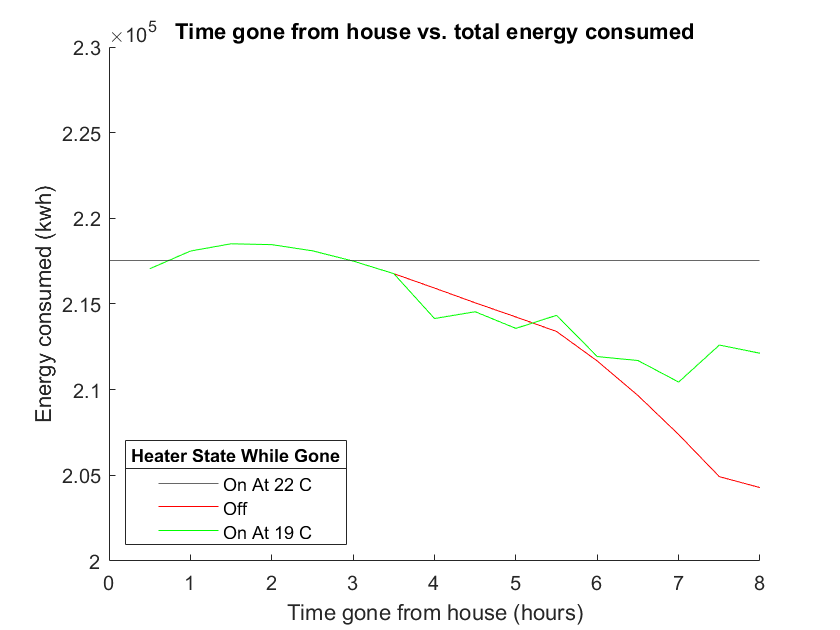

clf; hold on;
title('Time gone from house vs. total energy consumed')
yline(energy_use_with_22_c) % keep on at 22 c
plot(sweep_results(:,1), sweep_results(:,2), 'r') % turn off
plot(sweep_results(:,1), sweep_results(:,3), 'g') % turn down to lower temp
ylim([2*10^5, 2.3*10^5])
xlabel('Time gone from house (hours)')
% yline(energy_use_with_19_c) % keep on at 19 c
ylabel("Energy consumed (kwh)")
leg = legend("On At 22 C", "Off", "On At 19 C", "Location", "Southwest");
title(leg,'Heater State While Gone')

hour_leave_house = 9; % time you leave the house in hours (military) 
simulation_length = 24; % run simulation for 24 hours each time 
time_gone = 2;
time_until_end_of_simulation = simulation_length - time_gone - hour_leave_house;

turn_off_range = [(ideal_temp)*ones(1,hour_leave_house*hours_to_seconds), (effective_off_temp)*ones(1,time_gone*hours_to_seconds), (ideal_temp)*ones(1,time_until_end_of_simulation*hours_to_seconds)];

[time_range, temperature, energy_consumption, turn_off_on_time, outside_temp] = house_cooling(turn_off_range, ideal_temp);

X = [time_range; temperature; energy_consumption]'
time_after_return = (hour_leave_house+time_gone) * hours_to_seconds
X_time_after_return = X(time_after_return:(simulation_length * hours_to_seconds),:)
energy_consumption_at_9_am = X(9*hours_to_seconds,3)
for i=1:size(X_time_after_return,1)
    if X_time_after_return(i,2) > ideal_temp
        energy_consumption_when_house_returns_to_normal_temp = X_time_after_return(i,3);
        (time_after_return + i) / hours_to_seconds
        break
    end
end
energy_consumption_when_house_returns_to_normal_temp

time_gone = 0

time_gone = 1

time_gone = 2

time_gone = 3

time_gone = 4

time_gone = 5

time_gone = 6

time_gone = 7

time_gone = 8

want to compare energy expended between on: leaving and come back; off: leaving and when temp is reached ideal

Getting only the energy consumed up until the ideal 

hour_leave_house = 9; % time you leave the house in hours (military) 

sweep_results = 	1.0e+08 *

         0         0         0         0
    0.0000    0.4705   -0.0000         0
    0.0000    0.8508   -0.0000         0
    0.0000    1.1730   -0.0000         0
    0.0000    1.4732   -0.0001         0
    0.0000    1.7732   -0.0001         0
    0.0000    2.0850   -0.0001         0
    0.0000    2.4125   -0.0001         0
    0.0000    2.7542   -0.0001         0


simulation_length = 24;
% simulation_length = 48; % how long to run simulation for

% sweep time_gone
sweep_range = [0:1:8];
% sweep_range = [0:1:4]

sweep_results = zeros(size(sweep_range, 2), 4);

for i = 1:size(sweep_range, 2)
    time_gone = sweep_range(i)
    time_until_end_of_simulation = simulation_length - time_gone - hour_leave_house;
    

sweep_results = 	1.0e+08 *

         0         0         0         0
    0.0000    0.4705   -0.0000    0.3670
    0.0000    0.8508   -0.0000    0.6607
    0.0000    1.1730   -0.0000    0.9445
    0.0000    1.4732   -0.0001    1.2777
    0.0000    1.7732   -0.0001    1.4995
    0.0000    2.0850   -0.0001    1.7230
    0.0000    2.4125   -0.0001    2.0530
    0.0000    2.7542   -0.0001    2.2933


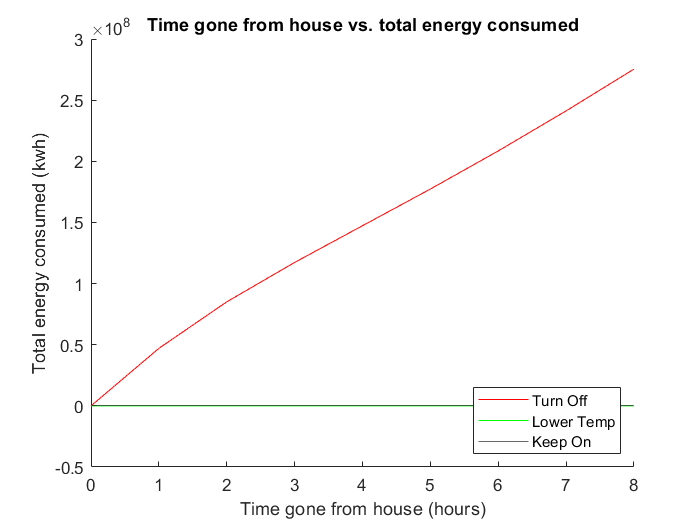

    turn_off_range = [(ideal_temp)*ones(1,hour_leave_house*hours_to_seconds), (effective_off_temp)*ones(1,time_gone*hours_to_seconds), (ideal_temp)*ones(1,time_until_end_of_simulation*hours_to_seconds)];
    turn_down_range = [(ideal_temp)*ones(1,hour_leave_house*hours_to_seconds), (down_temp)*ones(1,time_gone*hours_to_seconds), (ideal_temp)*ones(1,time_until_end_of_simulation*hours_to_seconds)];     
    
    [turn_off_time_range, turn_off_temperature, turn_off_energy_consumption, turn_off_on_time, turn_off_outside_temp] = house_cooling(turn_off_range, ideal_temp);
    [turn_down_time_range, turn_down_temperature, turn_down_energy_consumption, turn_down_on_time, turn_down_outside_temp] = house_cooling(turn_down_range, ideal_temp);
    
    [turn_off_energy_consumed_from_leave_to_normal_temp,turn_off_time_house_returns_to_normal_temp] = getEnergyConsumptionAtIdealTemp(hour_leave_house, time_gone, simulation_length, turn_off_time_range, turn_off_temperature, turn_off_energy_consumption);
    [turn_down_energy_consumed_from_leave_to_normal_temp,turn_down_time_house_returns_to_normal_temp] = getEnergyConsumptionAtIdealTemp(hour_leave_house, time_gone, simulation_length, turn_down_time_range, turn_down_temperature, turn_down_energy_consumption);
    
    sweep_results(i, 1) = time_gone;

    sweep_results(i, 2) = turn_off_energy_consumed_from_leave_to_normal_temp;
    sweep_results(i, 3) = turn_down_energy_consumed_from_leave_to_normal_temp / (turn_down_time_house_returns_to_normal_temp - hour_leave_house*hours_to_seconds);
end
sweep_results

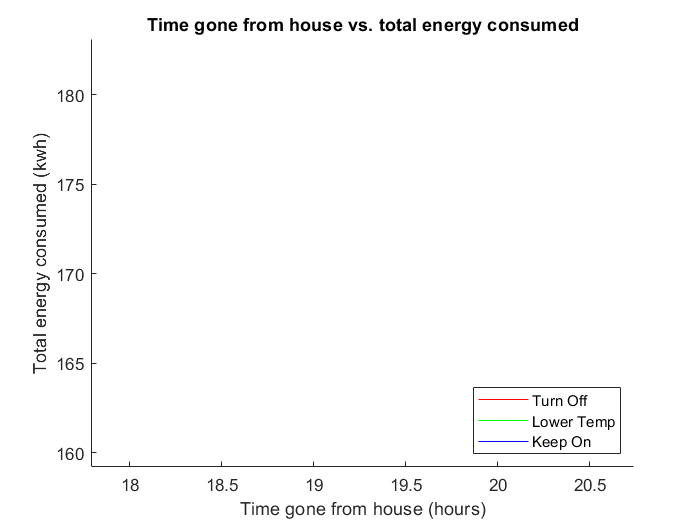

keep_on_range = [(ideal_temp)*ones(1,simulation_length*hours_to_seconds)];
[time_range, temperature, energy_consumption, turn_off_on_time, outside_temp] = house_cooling(keep_on_range, ideal_temp);
for i = 1:size(sweep_range, 2)
    time_gone = sweep_range(i);
    time_after_return = hour_leave_house + time_gone;
    [energy_consumed_from_leave_to_normal_temp,time_house_returns_to_normal_temp] = getEnergyConsumptionAtIdealTemp(hour_leave_house, time_gone, simulation_length, time_range, temperature, energy_consumption);
    sweep_results(i, 4) = energy_consumed_from_leave_to_normal_temp;
%     energy_consumption_at_return = energy_consumption(time_after_return * hours_to_seconds);

%     sweep_results(i, 4) = energy_consumption_at_return - energy_consumption_at_leave;
end
sweep_results

clf; hold on;
title('Time gone from house vs. total energy consumed')
plot(sweep_results(:,1), sweep_results(:,2), 'r') % turn off
plot(sweep_results(:,1), sweep_results(:,3), 'g') % turn down to lower temp
yline(heater_power) % keep on at 19 c
hold off;
legend("Turn Off", "Lower Temp", "Keep On", "Location", "Southeast")
xlabel('Time gone from house (hours)')
ylabel("Total energy consumed (kwh)")
clf; hold on;
title('Time gone from house vs. total energy consumed')
plot(sweep_results(:,1), sweep_results(:,2) / 3.6E6, 'r') % turn off
plot(sweep_results(:,1), sweep_results(:,3) / 3.6E6, 'g') % turn down to lower temp
plot(sweep_results(:,1), sweep_results(:,4) / 3.6E6, 'b') % keep on
hold off;
legend("Turn Off", "Lower Temp", "Keep On", "Location", "Southeast")
xlabel('Time gone from house (hours)')
% yline(energy_use_with_19_c) % keep on at 19 c
ylabel("Total energy consumed (kwh)")
xlim([17.79 20.74])
ylim([159.2 183.1])


## Interpretation

## Model Limitations and Future Development